# New case study

#### Case study:

Author: Oliver Schön, Birgit van Huijgevoort

This case study comprises ...

#### Initialization

clc; clear; close all;

% Add toolboxes to path
run Install.m

Please add either tensortoolbox or tensor lab to your path
 You can download the tensortoolbox for matlab from  https://www.tensortoolbox.org
MPT toolbox is not automatically installed
Yalmip and Mosek are not automatically installed


% Track runtime
tStart = tic;

## Specify system and regions

LTI system of the form

x(t+1) = A x(t) + B u(t) + Bw w(t) 

y(t) = C x(t) + D u(t)

% Define system parameters
A = [0.9, 0; 0, 0.8];%0.9 * eye(2);
B = 0.7 * eye(2)*2;
C = eye(2);
D = zeros(2);
Bw = eye(2);
dim = length(A);

% Specify mean and variance of disturbance w(t) 
mu = zeros(dim, 1); % Mean of disturbance
sigma = 0.2 * eye(dim); % Variance of disturbance

sysLTI = LinModel(A, B, C, D, Bw, mu, sigma);
 
% Bounds on state space 
x1l = -6; % Lowerbound in x1
x1u = 6; % Upperbound in x1
x2l = -6; % Lowerbound in x2
x2u = 6; % Upperbound in x2
sysLTI.X = Polyhedron(combvec([x1l, x1u], [x2l, x2u])');

% Bounds on  and input space
ul = [-1; -1]; % Lowerbound input u
uu = [1; 1]; % Upperbound input u
sysLTI.U = Polyhedron(combvec([ul(1), uu(1)], [ul(2), uu(2)])');

### Specify regions for the specification

Pick up a parcel at P1 and deliver it to P3. If on this path the agent passes P2, it loses the package and has to pick up a new one (at P1).

% NOTE, THESE REGIONS ARE DEFINED OVER THE OUTPUT SPACE!!!
% 1) Pick-up region
p1x = [5 5 6 6 5]; % x1-coordinates
p1y = [-1 1 1 -1 -1]; % x2-coordinates
P1 = Polyhedron([p1x; p1y]');

% 2) Region where you lose package
p2x = [0 0 1 1 0]; % x1-coordinates
p2y = [-5 1 1 -5 -5]; % x2-coordinates
P2 = Polyhedron([p2x; p2y]');

% 3) Delivery region
p3x = [-4 -4 -2 -2 -4];    % x1-coordinates
p3y = [-3 -4 -4 -3 -3];    % x2-coordinates  
P3 = Polyhedron([p3x; p3y]');

sysLTI.regions = [P1; P2; P3]; % regions that get specific atomic propositions
sysLTI.AP = {'p1', 'p2', 'p3'}; % with the corresponding atomic propositions

Plot_sysLTI(sysLTI)

## Synthesize scLTL formula (or input DFA yourself)

% Specify DFA directly
act = {' ', 'p3', 'p2', 'p2p3', 'p1', 'p1p3', 'p1p2', 'p1p2p3'};

trans = [ ...
    1, 1, 1, 1, 2, 2, 2, 2; ...
    2, 3, 1, 1, 2, 3, 1, 1; ...
    0, 0, 0, 0, 0, 0, 0, 0 ...
    ];

DFA = struct( ...
    'S', [1 2 3], ...
    'S0', 1, ...
    'F', 3, ...
    'act', {act}, ...
    'trans', trans, ...
    'sink', find([0, 0]) ... % Empty double row vector
    );

## Construct abstract model by gridding it

disp('Start gridding...');

Start gridding...


tGridStart = tic;

% Specify division of input space for actuation and feedback
ula = ul; % Part of input space for actuation (lowerbound)
uua = uu;
ulf = ul - ula; % Part of input space for feedback (lowerbound)
uuf = uu - uua;

% Specify granularity of abstraction/gridding
lu =3; % Division of input space
lx1 =400; % Division of state space in x1-direction
lx2 =400;% Division of state space in x2-direction
 

uhat = combvec(linspace(ula(1), uua(1), lu), linspace(ula(2), uua(2), lu));

l = [lx1, lx2]; % Number of grid cells in x1- and x2-direction
tol = 10^(-6);
sysAbs = Gridding(sysLTI, uhat, l, tol, 'TensorComputation', true);

% Save some extra system parameters into struct
sysAbs.orig = sysLTI;

% Label output space
regions = {p1x, p1y; p2x, p2y; p3x, p3y};
sysAbs = labelos(sysAbs, DFA, regions, sysLTI.AP);

tGridEnd = toc(tGridStart);
disp(['---> finished gridding in ', num2str(tGridEnd), ' seconds'])

---> finished gridding in 0.54067 seconds


## Compute delta based on epsilon

% Pick epsilon
epsilon = 0.075;
 

disp('Starting to compute delta for chosen epsilon...');

Starting to compute delta for chosen epsilon...


tSimStart = tic;

% Calculate delta based on chosen epsilon
[delta, D_m, K] = ComputeDelta(epsilon, sysLTI, sysLTI.mu, sysLTI.sigma, sysAbs.beta);

% Calculate simulation relation
rel = SimRel(epsilon, delta, D_m);

tSimEnd = toc(tSimStart);

disp(['delta = ', num2str(delta), ', epsilon = ', num2str(epsilon) ])

delta = 0.012766, epsilon = 0.075


disp(['---> finished computing eps delta in ', num2str(tSimEnd), ' seconds'] )

---> finished computing eps delta in 5.6234 seconds


## Synthesize controller

disp('Starting to compute robust controller...')

Starting to compute robust controller...


rel.NonDetLabels = NonDeterministicLabelling(sysAbs.outputs, sysLTI.regions, rel);

N = 60;     % time horizon

[satProp_, pol] = SynthesizeRobustController(sysAbs, DFA, rel, N, false);

 <---- Start computing robust policy 
Elapsed time is 0.053642 seconds.
Convergence reached!
Number of iteration required, k=34
Elapsed time is 0.777250 seconds.
 ----> Finished computing robust policy in 0.82131


tEnd = toc(tStart);
disp(['Total runtime = ', mat2str(tEnd), ' seconds'])

Total runtime = 12.570218542 seconds


## Show value function

[X1hat, X2hat] = ndgrid(sysAbs.hx{1}, sysAbs.hx{2});
satProp = satProp_(DFA.S0, :);
figure
surf(X1hat, X2hat, reshape(satProp, l(1), l(2)),'EdgeColor','interp')
xlabel('x_1')
ylabel('x_2')
zlim([0, 1])
title('Value function')

assert(max(satProp) > 0, "Satisfaction probability is zero everywhere. Terminating.")

## Start simulation

x0 = [-5;-5];
 
xsim = x0;
indexing = 1:length(sysAbs.states);

% Find initial abstract state
diff = abs(x0 .* ones(size(sysAbs.states)) - sysAbs.states);
inR = (([1 1] * ((D_m^.5 * diff).^2)).^.5) <= epsilon;
assert(sum(inR) > 0, "No valid state in relation found.")
indices_valid = indexing(inR);
[value_max, index_aux] = max(satProp(inR)); 
j = indices_valid(index_aux); % Find maximizing index of abstract state    
xhat0 = sysAbs.states(:, j);
xhatsim = xhat0;
q = DFA.S0; % Initial state of DFA
uhat_0 = pol(:, j, q(:, end));
u0 = uhat_0 + K * (x0 - xhat0);
ysim = sysLTI.C * x0 + sysLTI.D * u0;
q = [q, updateDFA(DFA, regions, sysLTI.AP, q(:, end), ysim(:,end))]; % Get q1
uhat = pol(:, j, q(:, end));

disp(['Satisfaction probability at xhat0 = ', num2str(satProp(j))])

Satisfaction probability at xhat0 = 0.79807


u = uhat + K * (x0 - xhat0);
for i = 1:N
    w1 = sysLTI.mu(1) + sqrt(sysLTI.sigma(1, 1)) .* randn(1);
    w2 = sysLTI.mu(2) + sqrt(sysLTI.sigma(2, 2)) .* randn(1);
    w = [w1; w2];

    % Compute next state
    xnext = sysLTI.A * xsim(:, i) + sysLTI.B * u + sysLTI.Bw * w;
    xsim = [xsim, xnext];
    ysim = [ysim, sysLTI.C * xsim(:, end)];

    % Find next abstract state by looking at the maximizer in R wrt the value
    % function
    inR = rel.inR(xsim(:, end), sysAbs.states);
    assert(sum(inR) > 0, "No valid state in relation found in iteration %i.", i)
    indices_valid = indexing(inR);
    [value_max, index_aux] = max(satProp(inR)); 
    j = indices_valid(index_aux); % find maximizing index of abstract state
    xhatnext = sysAbs.states(:, j);

    % Keep track of DFA
    q = [q, updateDFA(DFA, regions, sysLTI.AP, q(:, end), ysim(:,end))]; % Get qnext

    % Check whether specification satisfied
    if q(:, end) == DFA.F
        fprintf("Satisfaction after %d time steps.\n", i)
        break
    end

    % Compute next input
    uhat = [pol(:, j, q(:, end))];
    u = uhat + K * (xnext - xhatnext);
end

Satisfaction after 18 time steps.



% Check whether specification satisfied
if q(:, end) ~= DFA.F
    fprintf("Simulation finished after %d time steps without satisfying.\n", i)
end

## Show results

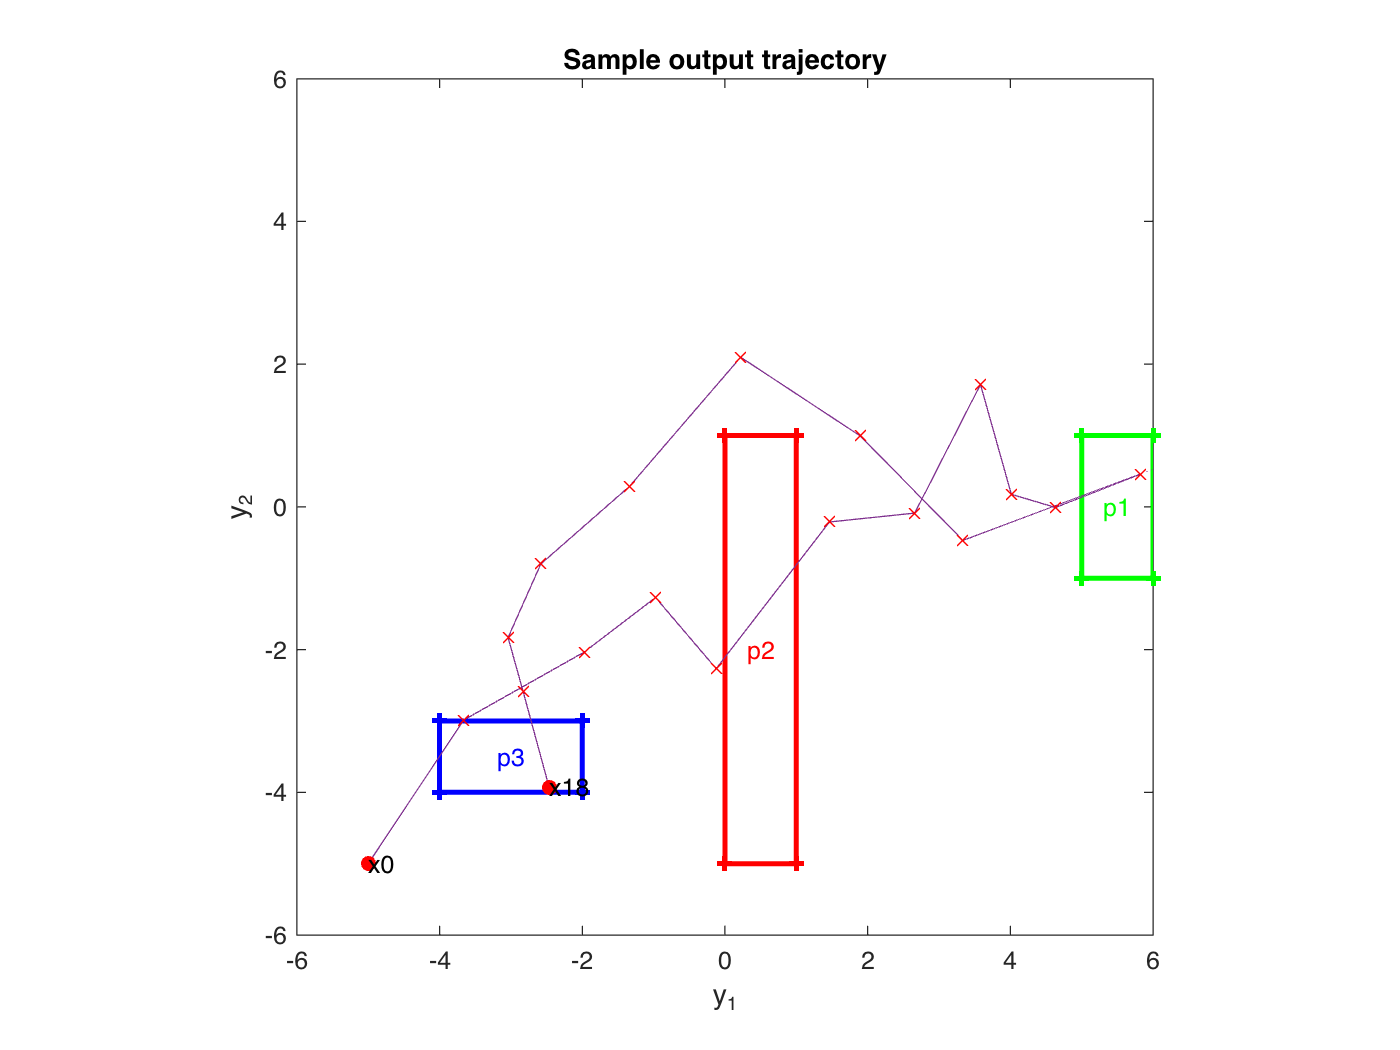

figure
plot(p1x, p1y, 'g+-', 'LineWidth', 2)
text((max(p1x)-min(p1x))/2 + min(p1x), (max(p1y)-min(p1y))/2 + min(p1y), ...
    'p1', 'Color', 'g', 'HorizontalAlignment', 'center')
axis equal
hold on
plot(p2x, p2y, 'r+-', 'LineWidth', 2)
text((max(p2x)-min(p2x))/2 + min(p2x), (max(p2y)-min(p2y))/2 + min(p2y), ...
    'p2', 'Color', 'r', 'HorizontalAlignment', 'center')
plot(p3x, p3y, 'b+-', 'LineWidth', 2)
text((max(p3x)-min(p3x))/2 + min(p3x), (max(p3y)-min(p3y))/2 + min(p3y), ...
    'p3', 'Color', 'b', 'HorizontalAlignment', 'center')
xlim([x1l x1u])
ylim([x2l x2u])
xlabel('y_1')
ylabel('y_2')
plot(ysim(1, :), ysim(2, :))
plot(ysim(1, :), ysim(2, :), 'rx')
scatter(x0(1), x0(2), 'ro', 'filled')
text(x0(1), x0(2), "x0")
scatter(ysim(1, end), ysim(2, end), 'ro', 'filled')
text(ysim(1, end), ysim(2, end), sprintf("x%d", i))
title("Sample output trajectory")